clear; close all, clc
% this is the true cessna 182
% note that insufficiently many lateral flap sections exist. at least 3
% spanwise flap sections are recomended per wing for desired lateral
% response.

% this is cals model
% currently roughly trimmed

## Define the simulation parameters

dt = .1; % time step (seconds)
t_total = 10 % total simulation time (seconds)

t_total = 10

angle = 5; % perturbed deflection (degrees)

disable_PAH = false; % use rigid flap?

k_command = .2; % comanded value of spring stiffness (N/m)
c_r_command = .05; % comanded value of rate damping ()
c_c_command = .005; % commanded value of coulomb damping ()
delt_0_command = deg2rad(5); % comanded value of deflection (rad)

I_flap = .9; % moment of inertia of flap about hinge line (kg*m^4)

% these are good if the initial flap angle is zero
x_0 = [k_command, c_r_command, c_c_command, delt_0_command, I_flap];
x_0 = [.2, .05, .0005, .087266, .9]; % pretty good values - optimal for the c310
x_0 = [-0.0518, 43.6289, 0.0005, 85.1409, 1.4451]; % optimal over 20 second window (very good)
x_0 = [0.6773, 11.2789, 0.0004, -2.0731, 16.5946]; % less optimal over 20 second window but positive
% x_0 = [-6.8349, 14.5220, 0.0004, 0.7776, 7.4999] % optimal over 150 seconds 
x_0 = [49.1721, 4.3322, 0.0005, -51.2147, 28.6414] % optimal over 10 seconds

## run base case - no PAH

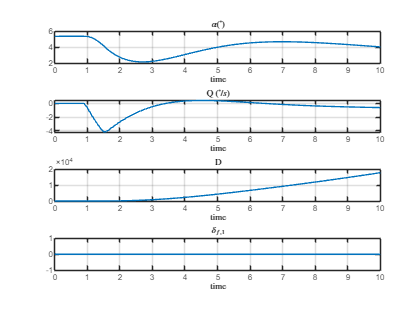

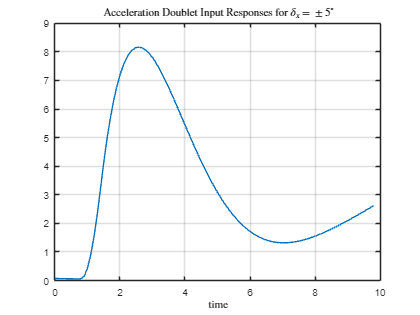

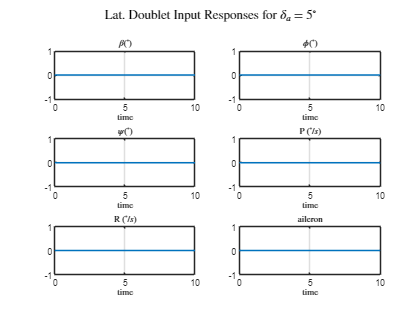

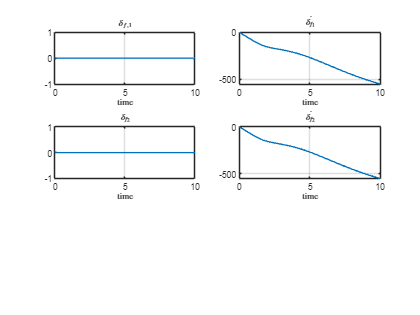

[y_all, time] = simulation(dt, t_total, angle, k_command, c_r_command, c_c_command, delt_0_command, I_flap, true);
plot_6dof_results(y_all, time, angle);

f = objective_function(x_0, dt, t_total, angle, true)

f = 0.1429


% % sys = ssest([time; y_all(1)],2)
% sys = ssest([time(1:end-2); diff(diff(y_all(12)))],2)
% frsys = idfrd(sys)
% % bode(frsys)
% figure;
% spectrum(frsys)

## Perform optimization

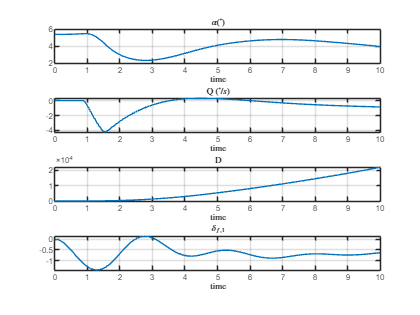

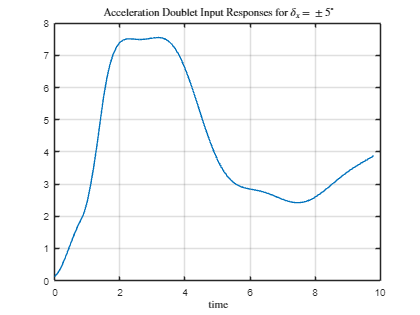

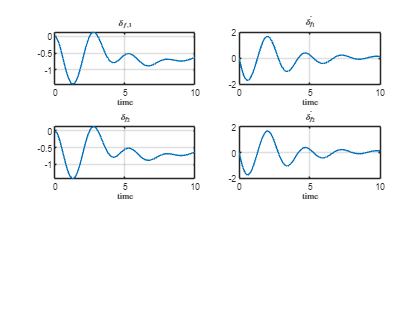

[y_all, time] = simulation(dt, t_total, angle, x_0(1), x_0(2), x_0(3), x_0(4), x_0(5), false);
plot_6dof_results(y_all, time, angle);

f = objective_function(x_0, dt, t_total, angle, false)

f = 0.1325


% Define the objective function
obv_fun = @(x) objective_function(x, dt, t_total, angle, false);

% Define the initial design variables

% Define the bounds for the design variables
% lb = [0, 0, .004, -1e1, 1e-6];
% ub = [1e1, 1e1, 1e1, 1e1, 1e1];
lb = [-5e1, 0, .0004, -1e2, 1e-9];
ub = [5e1, 5e1, .0005, 1e2, 5e1];
% bayesian optimization

% Define the optimization options
% options = optimoptions('ga', ... 
%     'Display', 'iter', ... 
%     'MaxGenerations', 10, ... 
%     'PopulationSize', 5, ... 
%     'UseParallel', true); 
% 
% options = optimoptions('ga', ... 
%     'Display', 'iter', ... 
%     'MaxGenerations', 2, ... 
%     'PopulationSize', 2, ... 
%     'UseParallel', false); 

% % Start the parallel pool 
% if isempty(gcp('nocreate'))
%     parpool;
% end 
% Perform the optimization using Genetic Algorithm
%[x_opt, f_opt] = ga(obv_fun, numel(lb), [], [], [], [], lb, ub, [], options);


% GA parameters - origianl
pop_size = 3; % Population size
max_generations = 4; % Number of generations
mutation_rate = 0.1; % Mutation rate
elite_size = 1; % Number of elite members to retain

% new GA paramters
pop_size = 50; % Population size
max_generations = 40; % Number of generations
mutation_rate = 0.3; % Mutation rate
elite_size = 3; % Number of elite members to retain

pop_size = 50; % Population size
max_generations = 20; % Number of generations
mutation_rate = 0.3; % Mutation rate
elite_size = 3; % Number of elite members to retain


% Initialize population
population = repmat(lb, pop_size, 1) + rand(pop_size, numel(lb)) .* repmat(ub - lb, pop_size, 1);

% Main GA loop
for generation = 1:max_generations
    % Evaluate fitness of each individual
    fitness = zeros(pop_size, 1);
    parfor i = 1:pop_size
        fitness(i) = objective_function(population(i, :), dt, t_total, angle, disable_PAH); % printing this is good to track progress
    end
    
    % Elitist selection
    [sorted_fitness, sorted_indices] = sort(fitness);
    elite_population = population(sorted_indices(1:elite_size), :);
    
    % Select individuals based on fitness (roulette wheel selection)
    fitness_sum = sum(fitness);
    fitness_prob = fitness / fitness_sum;
    selected_indices = randsample(1:pop_size, pop_size - elite_size, true, fitness_prob);
    selected_population = population(selected_indices, :);
    
    % Apply crossover and mutation
    new_population = selected_population;
    for i = 1:2:(pop_size - elite_size)
        if i+1 > (pop_size - elite_size), break; end
        % Crossover
        crossover_point = randi(numel(lb) - 1);
        new_population(i, crossover_point+1:end) = selected_population(i+1, crossover_point+1:end);
        new_population(i+1, crossover_point+1:end) = selected_population(i, crossover_point+1:end);
        
        % Mutation
        if rand < mutation_rate
            mutation_idx = randi(numel(lb));
            new_population(i, mutation_idx) = lb(mutation_idx) + rand * (ub(mutation_idx) - lb(mutation_idx));
        end
        if rand < mutation_rate
            mutation_idx = randi(numel(lb));
            new_population(i+1, mutation_idx) = lb(mutation_idx) + rand * (ub(mutation_idx) - lb(mutation_idx));
        end
    end
    
    % Update population with elite members
    population = [elite_population; new_population];
    
    % Display progress
    disp(['Generation: ', num2str(generation), ', Best Fitness: ', num2str(min(sorted_fitness))]);
end

Generation: 1, Best Fitness: 0.13141
Generation: 2, Best Fitness: 0.13141
Generation: 3, Best Fitness: 0.13141
Generation: 4, Best Fitness: 0.13141
Generation: 5, Best Fitness: 0.13141
Generation: 6, Best Fitness: 0.13141
Generation: 7, Best Fitness: 0.13141
Generation: 8, Best Fitness: 0.13141
Generation: 9, Best Fitness: 0.13067
Generation: 10, Best Fitness: 0.13067
Generation: 11, Best Fitness: 0.13067
Generation: 12, Best Fitness: 0.13067
Generation: 13, Best Fitness: 0.12998
Generation: 14, Best Fitness: 0.12998
Generation: 15, Best Fitness: 0.12998
Generation: 16, Best Fitness: 0.12998
Generation: 17, Best Fitness: 0.12998
Generation: 18, Best Fitness: 0.12998
Generation: 19, Best Fitness: 0.12998
Generation: 20, Best Fitness: 0.12998



% Find the best solution
x_opt = elite_population(1, :);
f_opt = sorted_fitness(1);

% Display the optimal solution
disp('Optimal design variables:'); 

Optimal design variables:


disp(x_opt); 

   49.1721    4.3322    0.0005  -51.2147   28.6414



disp('Optimal objective function value:');

Optimal objective function value:


disp(f_opt);

    0.1300





% Display the optimal solution
disp('Optimal design variables:'); 

Optimal design variables:


disp(x_opt); disp('Optimal objective function value:');

   49.1721    4.3322    0.0005  -51.2147   28.6414

Optimal objective function value:


disp(f_opt);

    0.1300



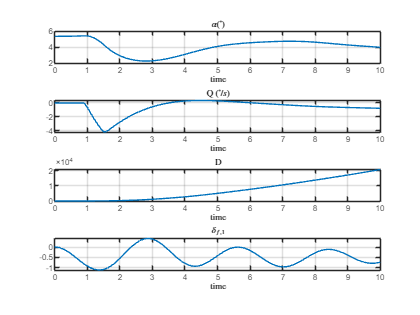

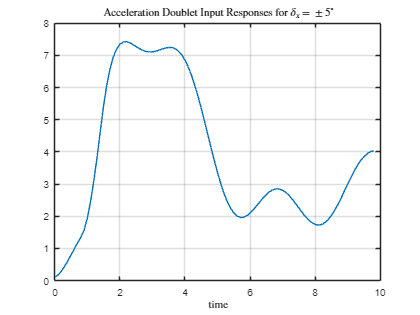

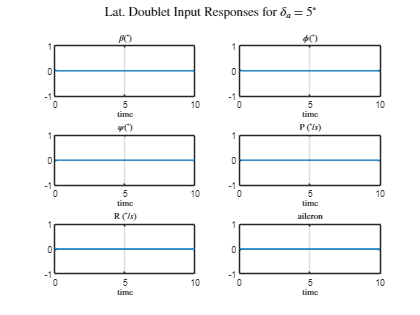

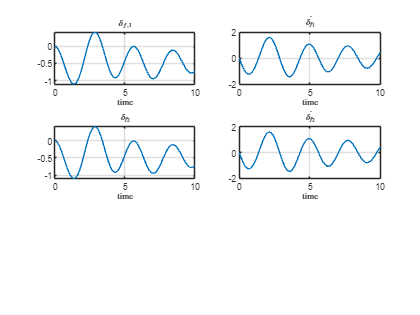


[y_all, time] = simulation(dt, t_total, angle, x_opt(1), x_opt(2), x_opt(3), x_opt(4), x_opt(5), false);
plot_6dof_results(y_all, time, angle);

function Xdot = aircraft(t, y, cv, stab_cont_derivs, I_flap, disablePAH)
    i = 1;
    states = y;
    controls = cv;
    
    VT      = states(0+i); %long
    alpha   = states(1+i); %long
    beta    = states(2+i);
    
    phi     = states(3+i);
    theta   = states(4+i); % long
    psi     = states(5+i);
    
    P       = states(6+i);
    Q       = states(7+i); %long
    R       = states(8+i);
    
    % Initial Control surfaces
    del_t_x   = states(12+i);
    del_e_x   = states(13+i);
    del_a_x   = states(14+i);
    del_r_x   = states(15+i);
    
    % PAH flap states
    % flap 1 (left)
    del_f_1  = states(16+i);
    del_f_dot_1  = states(17+i);
    % flap 2 (right)
    del_f_2  = states(18+i);
    del_f_dot_2  = states(19+i);

    % if disablePAH
    %     del_f_1 = 0;
    %     del_f_2 = 0;
    %     del_f_dot_1 = 0;
    %     del_f_dot_2 = 0;
    % end
    
    % Control inputs
    del_t   = controls(0+i);
    del_e   = controls(1+i);
    del_a   = controls(2+i);
    del_r   = controls(3+i);
    
    % PAH control inputs
    k = controls(4+i);
    c_r = controls(5+i);
    delta_0 = controls(6+i);
    c_c = controls(7+i);
    
    u = VT*cos(alpha)*cos(beta);
    v = VT*sin(beta);
    w = VT*sin(alpha)*cos(beta);
    
    % Constants
    % g = 32.14741; %ft/s2 %g*3.2808399;
    g = 31.7153794531126; % at 46000ft
    
    % Trim values
    alphatrim = deg2rad(5.38766545134696);%-deg2rad(5); % convert input trim to rad
    Ptrim        = 0; %(rad/s)
    Qtrim        = 0; %(rad/s)
    Rtrim        = 0; %(rad/s)
    VTtrim       = convvel(487.542331889981,"kts","ft/s"); %(ft/s)
    utrim        = VTtrim*cos(alphatrim); %(ft/s)
    
    S    = 932.57; %(ft2)
    cbar = 14.92; %(ft)
    b    = 76.80; %(ft)
    AR   = 6.32;
    mass = 74753; %(lbm)
    I_xx = 510417.5747; %(slug-ft2)
    I_yy =342708.943; %(slug-ft2)
    I_zz = 856772.3576; %(slug-ft2)
    I_xz = 23697.95883; %(slug-ft2)
    
    % Flap parameters
    c_f = convlength(4.42, "ft", "m"); % flap cord (m)
    C_h_0 = 0; % 0 angle of attack 0 deflection hinge moment (~)
    C_h_alpha = -.0584; % control surface hinge moment deriveative due to angle of attack (~)
    C_h_delta = -.363; % control surface moment derivative due to flap deflection (~)
    
    %TODO:  GET THE FLAP LOCATIONS FROM AINSLY!!!!!!!!!
    
    % location of Flap 1 (right wing)
    r_f_i_1 = [0; 0; 0]; % distance in body coordinates from the aircraft centre of gravity to the inboard most section of the control surface hingeline (m)
    r_f_o_1 = [0; 12.5416667; 0]; % distance in body coordinates from the aircraft centre of gravity to the outboard most section of the control surface hingeline (m)
    r_f_i_TE_1 = [-c_f; 0; 0]; % distance in body coordinates from the aircraft centre of gravity to the trailing edge of the inboard most section of the undeflected control surface (m)
    r_f_cg_B_1 = [0; 12.5416667/2; 0]; % distance in body coordinates from the aircraft centre of gravity to the location of the hingleline at the section of flap contining its centre of gravity (m)
    
    % location of flap 2
    r_f_i_2 = [0; -12.5416667; 0]; % distance in body coordinates from the aircraft centre of gravity to the inboard most section of the control surface hingeline (m)
    r_f_o_2 = [0; 0; 0]; % distance in body coordinates from the aircraft centre of gravity to the outboard most section of the control surface hingeline (m)
    r_f_i_TE_2 = [-c_f; -12.5416667; 0]; % distance in body coordinates from the aircraft centre of gravity to the trailing edge of the inboard most section of the undeflected control surface (m)
    r_f_cg_B_2 = [0; -12.5416667/2; 0]; % distance in body coordinates from the aircraft centre of gravity to the location of the hingleline at the section of flap contining its centre of gravity (m)
    
    
    
    % aircraft coefficients
    c_l_alpha_wf = 3.73207961646962; % lift coefficient of wing fuselage combination per radian (1/radian)
    c_l_alpha_h = 2.94941227370322; % lift coefficient of wing fuselage combination per radian (1/radian)
    tau_delta_f = .707184; % efficiency of flap (~) from roskam stability and control part 1 page 61 figure 2.23
    %TODO:  TAU_delta_f!!!!!!!!!
    eta_h = 1; % dynamic pressure ratio of horizontal tail to free stream (~)
    S_h = 157.7 * convlength(1,"ft","m")^2; % horizontal tail planform area (m^2)
    d_elpsilon_d_alpha_h = .3063; % downwash gradient on the horizontal tail (1/radians) from AAA (can also compute using roskam part 6 page 262)
    %I_h = .9;
    I_h = I_flap;
    
    % Stop spring range and coeffcient
    delta_min = -deg2rad(20); % minimum deflection angle (radians)
    delta_max = deg2rad(20); % maximum deflection angle (radians)
    k_stop = 1e6; % deflection limiting hardening spring stiffness N/(m^2)
    
    % Note to self: flip flap limits for left aeileron because positive and
    % negative may be flipped
    
    % steady state
    
    C_L1  = 0.533069540694801;
    C_m1  = 0.0101558840487444;
    C_mt1 = -0.0101558840487444;
    C_m1  = 0; % need these at zero for the aircraft to be stable
    C_mt1 = 0;
    
    % S&C derivatives
    C_D0bar   = 0.013;
    e=0.830582171991287;
    
    C_yda     = 0;
    C_Lq      = 4.20000045075878;
    C_Ladot   = 1.04384206161712;
    C_mtu     = 0.0318505879236872;
    C_mtalpha = 0;
    C_yb      = -0.419347403822892;      C_yp      = -0.0678333064636734;
    C_yr      = 0.200781324022505;       C_La      = 4.23019118620399;
    C_Lu      = 0.388965159696157;          C_lb      = -0.136742037421907;
    C_lp      = -0.368946189906605;      C_lr      = 0.211212543678017;
    C_ma      = -0.0707047506013262;      C_mq      = -14.5540215323377;
    C_madot   = -3.74990100895756;      C_mu      = -0.195820799924223;
    C_nb      = -0.0510739664594054;      C_np      = -0.0789812742799082;
    C_nr      = -0.1117066695305;     C_ydr     = 0.0480026076052465;
    C_ldela   = 0.0210299331545958;       C_ldelr   = 0.00211000186538708;
    C_ndela   = -0.00104347810799074;     C_ndelr   = -0.0299008393525857;
    C_Ldele   = 0.00122580271614145;        C_mdele   = -0.30869208318857;
    % C_yda     = -0.000161;
    % C_mtu     = 0;
    % C_mtalpha = 0;
    
    mass = mass/g; % lbm to slug
    rho  = 0.00044; % slug/ft^3
    qbar = 0.5*rho*(VT^2);
    
    % aero forces and moment
    C_L  = C_L1 + C_La*(alpha - alphatrim) + (C_Lq*(Q - Qtrim)*(cbar/2))/utrim + (C_Lu*(u - utrim))/utrim + C_Ldele*(del_e_x ) + (1/2) * C_La* tau_delta_f * del_f_1 + (1/2) * C_La* tau_delta_f * del_f_2 ; % be careful with sign of flap deflection for left flap
    C_D  = C_D0bar + (C_L^2)/(pi*AR*e); % flap drag not implemented
    
    C_Y  = C_yb*beta + (C_yp*(P - Ptrim)*(b/2))/utrim + (C_yr*(R - Rtrim)*(b/2))/utrim + C_yda*del_a_x + C_ydr*del_r_x; % flap induced adverse yaw not modeled
    C_ls = C_lb*beta + (C_lp*(P - Ptrim)*(b/2))/utrim + (C_lr*(R - Rtrim)*(b/2))/utrim + C_ldela*del_a_x + C_ldelr*del_r_x - (1/2) * C_La* tau_delta_f * del_f_1 * r_f_cg_B_1(2) - (1/2) * C_La* tau_delta_f * del_f_2 * r_f_cg_B_2(2);
    % note: flap moment not implemented - considered negigible
    C_ms = C_m1 + C_ma*(alpha - alphatrim) + (C_mq*(Q - Qtrim)*(cbar/2))/utrim + (C_mu*(u - utrim))/utrim + C_mdele*(del_e_x ) + ...
        2*(C_m1*(u - utrim))/utrim + (C_mtu + 2*C_mt1)*(u - utrim)/utrim + C_mtalpha*(alpha - alphatrim);
    % flap yaw moments not implemented
    C_ns = C_nb*beta + (C_np*(P - Ptrim)*(b/2))/utrim + (C_nr*(R - Rtrim)*(b/2))/utrim + C_ndela*(del_a_x) + C_ndelr*del_r_x;
    C_xa = C_L*sin(alpha) - C_D*cos(alpha);
    C_ya = C_Y;
    C_za = -C_L*cos(alpha) - C_D*sin(alpha);
    C_l  = C_ls*cos(alpha) - C_ns*sin(alpha);
    C_m  = C_ms;
    C_n  = C_ls*sin(alpha) + C_ns*cos(alpha);
    
    %Thrust model
    %???????????????????????????????????????????????????????????????????????????????????????????????
    T = 6382.09494583848;
    T = 4.246740932008352e+03; % this is trimmed with elevator
    T = 4.246738835832848e+03; % this is trimmed without elevator
    
    % grav accel
    g_x = -g*sin(theta);
    g_y = g*sin(phi)*cos(theta);
    g_z = g*cos(phi)*cos(theta);
    
    % body accel
    a_x = (qbar*S*C_xa + T)/mass;
    a_y = (qbar*S*C_ya)/mass;
    a_z = (qbar*S*C_za)/mass;
    
    % moment
    L = C_l*qbar*S*b;
    M = C_m*qbar*S*cbar;
    N = C_n*qbar*S*b;
    % Differential equations:
    % Body linear velocities
    udot = a_x + g_x + R*v - Q*w;
    vdot = a_y + g_y - R*u + P*w;
    wdot = a_z + g_z + Q*u - P*v;
    
    % Total velocity and airflow angles
    VTdot    = (u*udot + v*vdot + w*wdot)/VT;
    alphadot = (u*wdot - w*udot)/((u^2) + (w^2));
    betadot  = ((VT*vdot - v*VTdot)/((u^2) + (w^2)))*cos(beta);
    %betadot  = (vdot*((u^2) + (w^2)) - v*(u*udot + w*wdot))/((VT^2)*(sqrt((u^2) + (w^2))));
    
    
    
    % Body angular velocities
    Pdot = (I_zz*L + I_xz*N - (I_xz*(I_yy - I_xx - I_zz)*P + ((I_xz^2) + I_zz*(I_zz - I_yy))*R)*Q)/(I_xx*I_zz - (I_xz^2));
    Qdot = (M - (I_xx - I_zz)*P*R - I_xz*((P^2) - (R^2)))/I_yy;
    Rdot = (I_xz*L + I_xx*N + (I_xz*(I_yy - I_xx - I_zz)*R + ((I_xz^2) + I_xx*(I_xx - I_yy))*P)*Q)/(I_xx*I_zz - (I_xz^2));
    
    % Inertial (Euler) angles
    phidot   = P + (R*cos(phi) + Q*sin(phi))*tan(theta);
    thetadot = Q*cos(phi) - R*sin(phi);
    psidot   = (Q*sin(phi) + R*cos(phi))/cos(theta);
    
    % Inertial position dynamics
    x_Idot = (cos(theta)*cos(psi))*u + (-cos(phi)*sin(psi) + sin(phi)*sin(theta)*cos(psi))*v + (sin(phi)*sin(psi) + cos(phi)*sin(theta)*cos(psi))*w;
    y_Idot = (cos(theta)*sin(psi))*u + (sin(phi)*sin(theta)*sin(psi) + cos(phi)*cos(psi))*v + (cos(phi)*sin(theta)*sin(psi) - sin(phi)*cos(psi))*w;
    z_Idot = (-sin(theta))*u + (sin(phi)*cos(theta))*v + (cos(phi)*cos(theta))*w;
    
    % Control surface dynamics
    Athrottle=-7;
    Bthrottle=7;
    Aelevator=-30;
    Belevator=30;
    Aaileron=-30;
    Baileron=30;
    Arudder=-30;
    Brudder=30;
    
    del_tdot = Athrottle*del_t_x + Bthrottle*del_t;
    del_edot = Aelevator*del_e_x + Belevator*del_e;
    del_adot = Aaileron*del_a_x + Baileron*del_a;
    del_rdot = Arudder*del_r_x + Brudder*del_r;
    
    % get flap angle
    %q_bar = 1/2 * rho * VT^2; % dynamic pressure (Pa)
    % 
    % determine prefered damping constant
    % set c_r for airfoil responce properties
    %zeta = .7; % damping ratio
    %mu = 4*I_h* (q_bar * c_f^2 * C_h_delta - k); % airfoil responce parameter
    % set damping to make that true (note culombic damping will be suboptimal
    %c_d = 2*I_h*zeta * sqrt(-mu * (2*I_h*zeta - 1) * (2*I_h*zeta + 1)) / (4*I_h^2*zeta^2-1); % total damping coefficient
    % unsure if i should use the one that acounts for culombic damping (good
    % near fp) or the one that doesn't (good far from f.p.) I think that as
    % this is transient responce culombic damping should be acounted for
    %c_r = max(c_d - c_c,0); % for now I will comment out this to disable 
    
    
    % Adaptive_Airfoil_Dynamics is outdated 
    %df = Adaptive_Airfoil_Dynamics(t, [del_f, del_f_dot], I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, alpha, q_bar);
    df_1 = Adaptive_Aerocompliant_Airfoil_Dynamics(t, [del_f_1, del_f_dot_1], I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, delta_min, delta_max, k_stop, r_f_i_1, r_f_o_1, r_f_i_TE_1, r_f_cg_B_1, rho, [u;v;w], [P;Q;R]);
    del_f_dot_1 = df_1(1);
    del_f_dotDot_1 = df_1(2);
    
    df_2 = Adaptive_Aerocompliant_Airfoil_Dynamics(t, [del_f_2, del_f_dot_2], I_h, k, delta_0, c_r, c_c, c_f, C_h_0, C_h_alpha, C_h_delta, delta_min, delta_max, k_stop, r_f_i_2, r_f_o_2, r_f_i_TE_2, r_f_cg_B_2, rho, [u;v;w], [P;Q;R]);
    del_f_dot_2 = df_2(1);
    del_f_dotDot_2 = df_2(2);
    
    
    if disablePAH
        del_f_dot_1 = 0;
        del_f_dot_2 = 0;
    end
    
    Xdot = [VTdot; alphadot; betadot; phidot; thetadot; psidot; Pdot; ...
        Qdot; Rdot; x_Idot; y_Idot; z_Idot; del_tdot; del_edot; del_adot; del_rdot; del_f_dot_1; del_f_dotDot_1; del_f_dot_2; del_f_dotDot_2];
end

function [y_all, time] = simulation(dt, t_total, angle, k_command, c_r_command, c_c_command, delt_0_command, I_flap, disable_PAH)
    % define IC and controls
    time = [0:dt:t_total]';
    t_0 = 1;
    t_end = length(time);
    
    %elevator trim angle
    delta_e_trim = deg2rad(-1.3683881539243);
    delta_e_trim = deg2rad(0);
    alpha_trim = deg2rad(5.38766545134696);%+deg2rad(2);


    throttle = zeros(size(time));
    elevator = ones(size(time))* deg2rad(delta_e_trim);
    aileron = zeros(size(time));
    rudder = zeros(size(time));
    elevator(1/dt:1.5/dt) = ones(size(1/dt:1.5/dt)).*angle.*pi./180 + deg2rad(delta_e_trim);
    %aileron(1/dt:1.5/dt) = ones(size(1/dt:1.5/dt)).*angle.*pi./180;
    
    k = ones(size(time)) .* k_command; % PAH spring const
    c_r = ones(size(time)) .* c_r_command; % rate damping coefficient (N*s/rad^2)
    c_c = ones(size(time)) .* c_c_command; % coulomb damping coefficient (N*s/rad^2)
    delta_0 = zeros(size(time)); % commanded deflection (radians)
    % delta_0 = ones(size(time)) .* delt_0_command; % commanded deflection (radians)
    % colombic damping coefficient (N)pm
    
    %k = k + .03*randn(size(time));
    %delta_0 = delta_0 + .003*randn(size(time));
    
    
    % elevator(1.5/dt:2/dt) = ones(size(1.5/dt:2/dt)).*angle.*-pi./180.;
    % elevator = elevator  + .003*randn(size(elevator));
    VT = zeros(size(time));
    VT(1) = convvel(487.542331889981,"kts","ft/s");
    Alphaest = ones(size(time))*alpha_trim; % if i starrt thisa a number that is not trim then i get the response to an alpha disturbance
    Betaest = zeros(size(time));
    phi = zeros(size(time));
    theta = zeros(size(time));
    theta = ones(size(time))*alpha_trim;
    psi = zeros(size(time));
    P = zeros(size(time));
    Q = zeros(size(time));
    R = zeros(size(time));
    ned = [zeros(size(time)),zeros(size(time)),zeros(size(time))];
    delta_f_1 = 0; % inital flap 1 position
    delta_f_dot_1 = 0; % initial flap 1 rate
    delta_f_2 = 0; % inital flap 2 position
    delta_f_dot_2 = 0; % initial flap 2 rate

    % try this
    % delta_f_1 = delt_0_command; % inital flap 1 position
    % delta_f_dot_1 = 0; % initial flap 1 rate
    % delta_f_2 = delt_0_command; % inital flap 2 position
    % delta_f_dot_2 = 0; % initial flap 2 rate
    
    cv = [throttle,   elevator ,   aileron  ,   rudder, k, c_r, delta_0, c_c];
    X_0 = [VT(1), Alphaest(1), Betaest(1), phi(1), theta(1), psi(1), ...
        P(1), Q(1), R(1), ned(1,1), ned(1,2), -ned(1,3), throttle(t_0), elevator(t_0) , ...
        aileron(t_0) , rudder(t_0),...
        delta_f_1, delta_f_dot_1, delta_f_2, delta_f_dot_2];
    
    y = X_0;
    
    %initialize y_all and t_all with IC as first element
    y_all = zeros([length(t_0:t_end),20]);       t_all = zeros([length(t_0:t_end),1]);
    y_all(1,:) = y;     t_all(1) = time(t_0);       J = 2;
    
    for i = (t_0):(length(time)-1)
        cv1 = cv(i,:); %update control inputs and time span for ODE45 each iteration
    
        % PID controller for the PAH
        %k(demanded)
    
        tspan = [time(i) time(i+1)];       dt = time(i+1) - time(i);
        [t,y] = ode45(@(t,y) aircraft(t, y, cv1, [], I_flap, disable_PAH), tspan, X_0);
        X_0 = y(size(y, 1),:);  % set new IC as ending state
        t_all(J) = t(end);       y_all(J,:) = y(end,:);
        J = J + 1; % indexer for recording y and t
    end
end

function f = objective_function(x, dt, t_total, angle, disable_PAH)
    % unpack x
    k_command = x(1); c_r_command = x(2); c_c_command = x(3); delt_0_command = x(4); I_flap = x(5);

    % run simulation
    %[y_all, time] = simulation(dt, t_total, angle, k_command, c_r_command, c_c_command, delt_0_command, I_flap, disable_PAH);
    [y_all, time] = simulation(dt, t_total, angle, k_command, c_r_command, 0, delt_0_command, I_flap, disable_PAH); % set couloub to 0

    % i dont think i need to do this but ben does it so i will keep it
    %13-16 are elevator alteroion etc.
    var_guid = {'U (ft/s)', '$\alpha (^\circ)$', '$\beta (^\circ)$', '$\phi (^\circ)$' '$\theta (^\circ)$', '$\psi (^\circ)$', 'P ($^\circ / s$)', 'Q ($^\circ / s$)','R ($^\circ / s$)','N' ,'E' ,'D', 'throttle', 'elevator', 'aileron', 'rudder', '$\delta_{f,1}$', '$\dot{\delta_{f_1}}$','$\delta_{f_2}$', '$\dot{\delta_{f_2}}$'};
    for ii = 1:length(var_guid)
        Vname{ii} = y_all(:,ii);
    end

    % we will minimize maximum total acceleration
    f = max(sqrt( diff(diff(Vname{10})).^2 + diff(diff(Vname{11})).^2 + diff(diff(Vname{12})).^2 ));
end

function plot_6dof_results(y_all, time, angle)
    %Convert to deg
    y_all(:,2:end) = y_all(:,2:end)*180/pi;
    
    %13-16 are elevator alteroion etc.
    var_guid = {'U (ft/s)', '$\alpha (^\circ)$', '$\beta (^\circ)$', '$\phi (^\circ)$' '$\theta (^\circ)$', '$\psi (^\circ)$', 'P ($^\circ / s$)', 'Q ($^\circ / s$)','R ($^\circ / s$)','N' ,'E' ,'D', 'throttle', 'elevator', 'aileron', 'rudder', '$\delta_{f,1}$', '$\dot{\delta_{f_1}}$','$\delta_{f_2}$', '$\dot{\delta_{f_2}}$'};
    
    % Plot Longitudinal variables (VT, VT_guid, theta, theta_guid, Q, del_t, del_e)
    for ii = 1:length(var_guid)
        Vname{ii} = y_all(:,ii);
    end
    
    figure
    ii = 0;
    for i = [2,8,12,17] %7,9
        ii = ii + 1;
        subplot(4,1,ii)
        plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
        %title(['Doublet Input Responses for $\delta_x$ = $\pm$', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
    end
    
    figure
    plot(time(1:end-2),diff(diff(Vname{12}))), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
    title(['Acceleration Doublet Input Responses for $\delta_x$ = $\pm$', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
    
    % latteral plots
    figure
    ii=0;
    for i = [3 4 6 7 9, 15]
        ii = ii + 1;
        subplot(3,2,ii)
        plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
    end
    sgtitle(['Lat. Doublet Input Responses for $\delta_a$ = ', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
    
    
    % PAH plots
    figure
    ii=0;
    for i = [17,18,19,20]
        ii = ii + 1;
        subplot(3,2,ii)
        plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
    end

    % figure;
    % sys = ssest([time(1:end-2); diff(diff(y_all(12)))],2);
    % frsys = idfrd(sys);
    % spectrum(frsys);
end